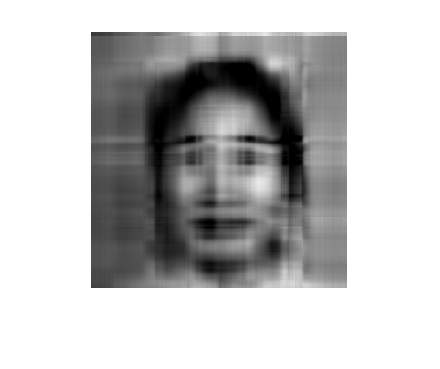

img_folder='../../PCA_Dataset/';
img_file=dir(fullfile(img_folder,'*.*'));
num_images=length(img_file);
random_index=randi(num_images);
random_image_name=fullfile(img_folder,img_file(random_index).name);
random_img=imread(random_image_name);
random_img=double(random_img);


mean_img=mean(random_img(:));
random_img=random_img-mean_img;


[row,col]=size(random_img);
cov_mat=(random_img' * random_img)/(row-1);


[eigvec,eigval]=eig(cov_mat);
[eigval,idx]=sort(diag(eigval),'descend');
eigvec=eigvec(:,idx);


num_of_components=5;


recon=random_img* eigvec(:,1:num_of_components) * eigvec(:,1:num_of_components)' +mean_img;
recon=uint8(recon);
imshow(recon)